## ENGI9804 Image Processing and Applications Lab3

### Part 1: Low pass and High pass filter design

1.Download the test image (puppy.jpg) and lp hp filters.m from D2L under Lab 3 and save it in the MATLAB working directory. Read the file and understand the implementation.

2. Read the image and convert the image to a grayscale image. Obtain the padding parameters and FT the image.

F_rgb=imread('puppy.jpg'); % read the gs image
F=rgb2gray(F_rgb);
im_size=size(F); % Obtain the size of the image
P=2*im_size(1);Q=2*im_size(2); % Optaining padding parameters as 2*image size
FTIm=fft2(double(F),P,Q); % FT with padded size

3. Design the ILPF

D0 = 0.1*im_size(1); %Cutoff freqency radius is 0.1 times the hight of the image
n=0;    %For use only in Butterworth filters. For BTW filters, Order(n)>0
%Filter_type=('ideal' or 'btw' or 'gaussian')
%lp_or_hp=('lp' or 'hp' for low pass or high pass),
Filter = lp_hp_filters('ideal','lp', P, Q, D0,n); % Calculate the LPF

4. Implement the filter by multiplying the FT of the image with filter. Undo padding.

Filtered_image=real(ifft2(Filter.*FTIm)); % multiply the FT of image by the filter and apply the IDFT
Filtered_image=Filtered_image(1:im_size(1), 1:im_size(2)); % Resize the image ( undo padding)

5. Move the origin of frequency spectrum to the center and display the results

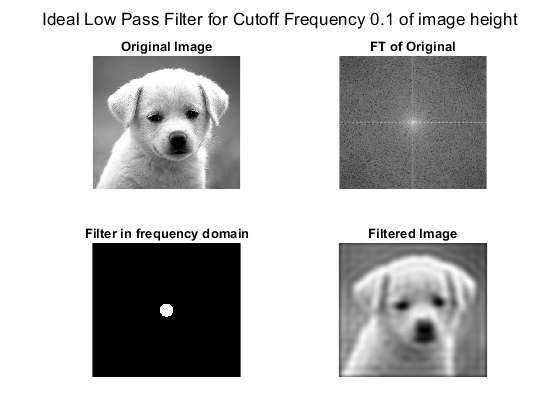

Fim=fftshift(FTIm); % move the origin of the FT to the center
FTI=log(1+abs(Fim)); % compute the magnitude (log to brighten display)
Ff=fftshift(Filter); % move the origin of the FT to the center
FTF=log(1+abs(Ff)); % compute the magnitude (log to brighten display)
figure(1);
sgtitle('Ideal Low Pass Filter for Cutoff Frequency 0.1 of image height');
subplot(2,2,1), imshow(F,[]), title('Original Image'); % show the image
subplot(2,2,2), imshow(FTI,[]), title('FT of Original'); % show the image
subplot(2,2,3), imshow(FTF,[]), title('Filter in frequency domain'); % filter
subplot(2,2,4), imshow(Filtered_image,[]), title('Filtered Image'); % show the image

### Part 2

In order to save effort, I abstracted the above code into a function "filter_plot".

1. Implement an Ideal low pass filter for cutoff frequencies (0.3 and 0.7 of image height).

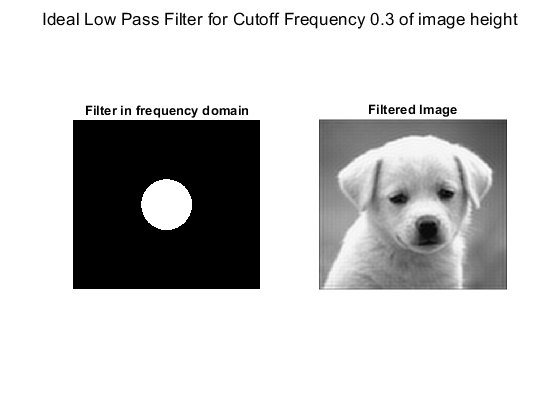

D0 = 0.3*im_size(1); %Cutoff freqency radius is 0.3 times the hight of the image
n=0;
Filter = lp_hp_filters('ideal','lp', P, Q, D0,n); % Calculate the LPF
imtitle = 'Ideal Low Pass Filter for Cutoff Frequency 0.3 of image height';
filter_plot(Filter, imtitle, F);

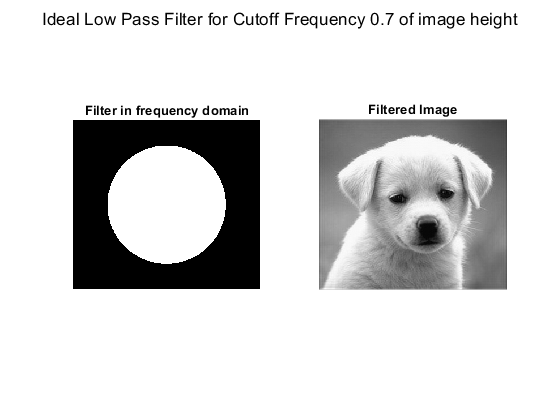


D0 = 0.7*im_size(1); %Cutoff freqency radius is 0.7 times the hight of the image
n=0;
Filter = lp_hp_filters('ideal','lp', P, Q, D0,n); % Calculate the LPF
imtitle = 'Ideal Low Pass Filter for Cutoff Frequency 0.7 of image height';
filter_plot(Filter, imtitle, F);

2. Implement a Butterworth low pass filter for cutoff frequencies (0.1 and 0.5 of image height) and order n = 1, 5, 20.

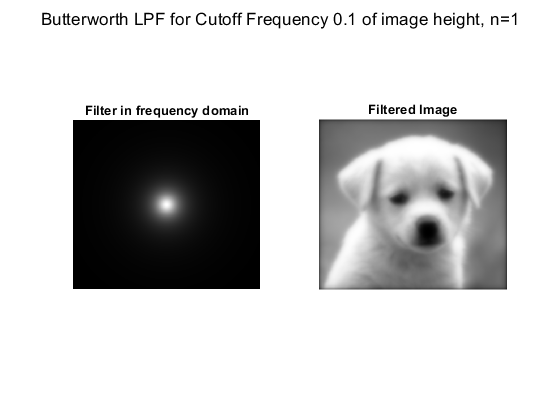

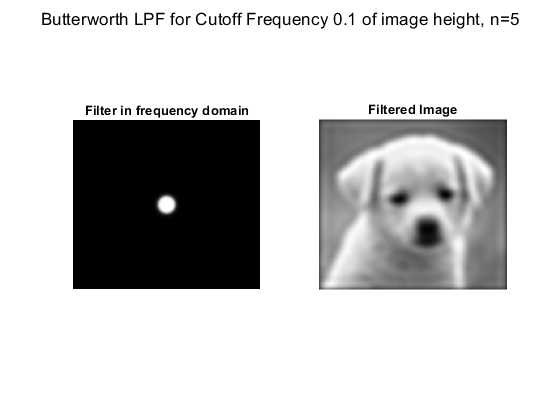

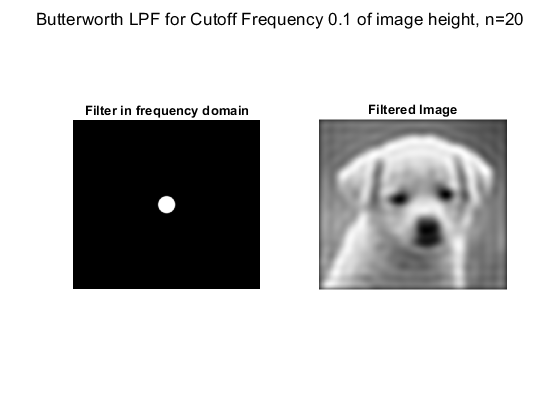

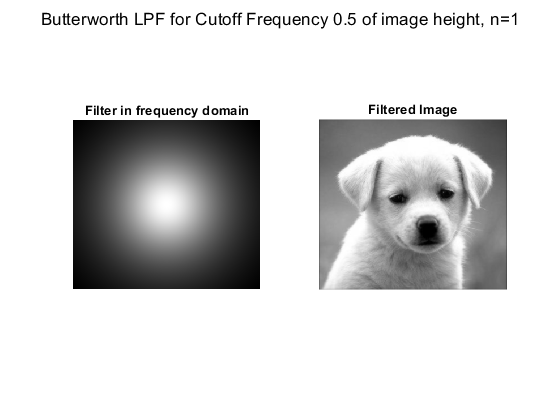

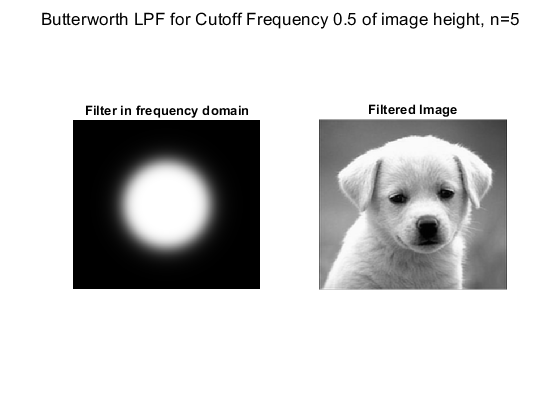

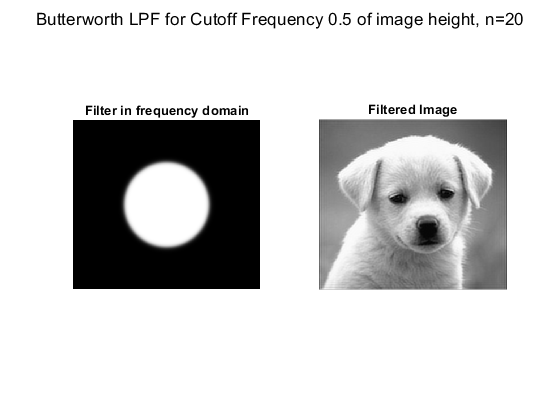

for j = [0.1, 0.5]
    for n = [1, 5, 20]
        D0 = j*im_size(1); 
        Filter = lp_hp_filters('btw','lp', P, Q, D0,n); % Calculate the LPF
        imtitle = sprintf('Butterworth LPF for Cutoff Frequency %.1f of image height, n=%d', j,  n);
        filter_plot(Filter, imtitle, F);
    end
end

3. Implement a Gaussian low pass filter for cutoff frequencies (0.1, 0.3 and 0.7 of image height) .

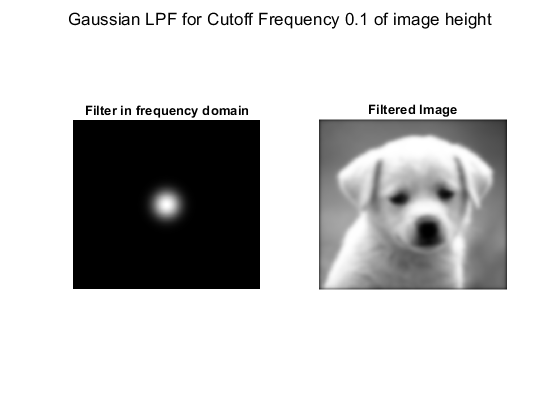

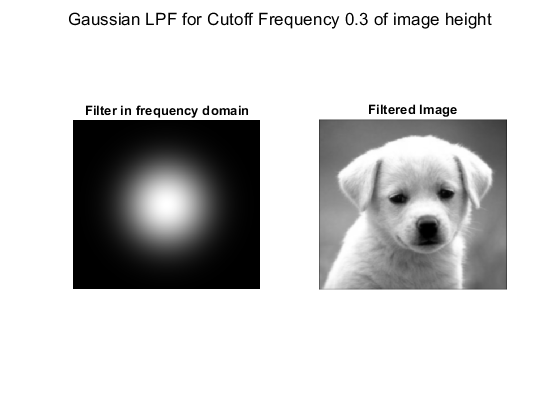

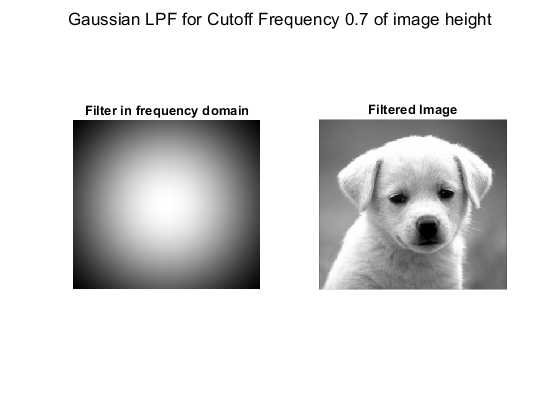

for j = [0.1, 0.3, 0.7]
    D0 = j*im_size(1); 
    n = 0;
    Filter = lp_hp_filters('gaussian','lp', P, Q, D0,n); % Calculate the LPF
    imtitle = sprintf('Gaussian LPF for Cutoff Frequency %.1f of image height', j);
    filter_plot(Filter, imtitle, F);
end

4. Implement an Ideal high-pass filter for cutoff frequencies (0.1, 0.3 and 0.7 of image height).

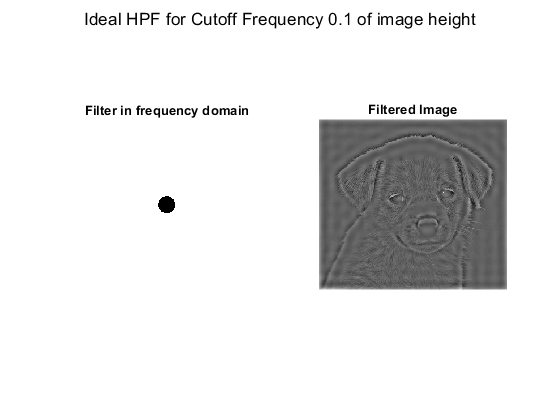

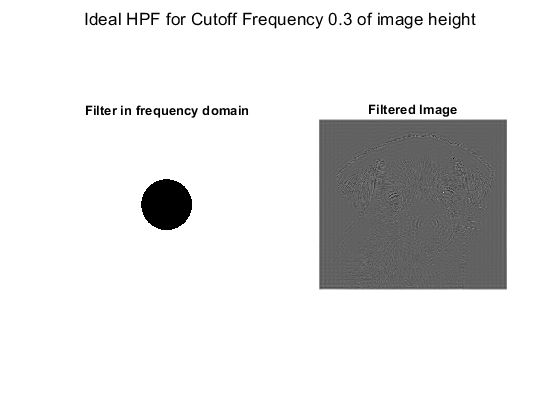

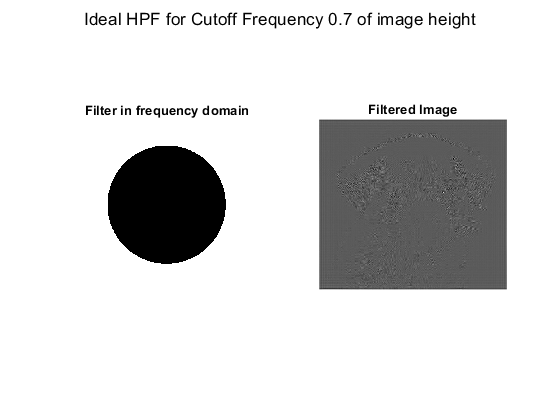

for j = [0.1, 0.3, 0.7]
    D0 = j*im_size(1); 
    n = 0;
    Filter = lp_hp_filters('ideal','hp', P, Q, D0,n); % Calculate the LPF
    imtitle = sprintf('Ideal HPF for Cutoff Frequency %.1f of image height', j);
    filter_plot(Filter, imtitle, F);
end

5. Implement a Butterworth high pass filter for cutoff frequencies (0.1 and 0.5 of image height) and order n = 1, 5, 20.

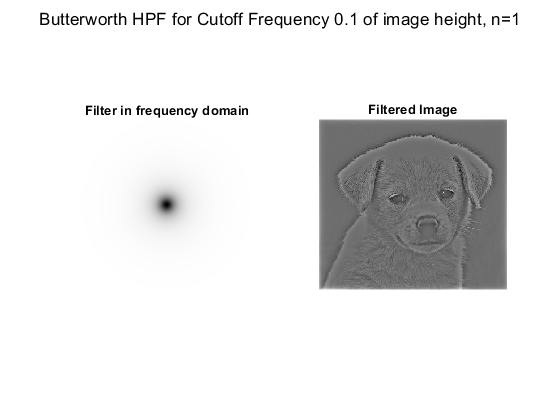

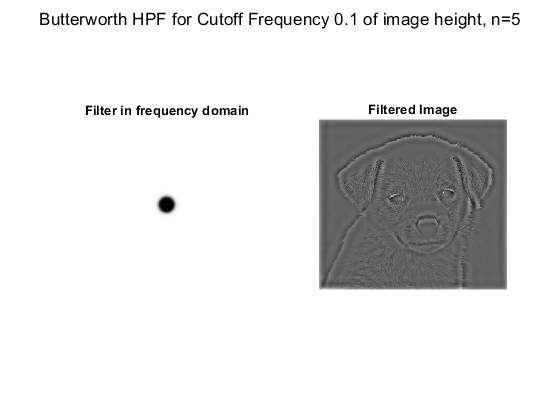

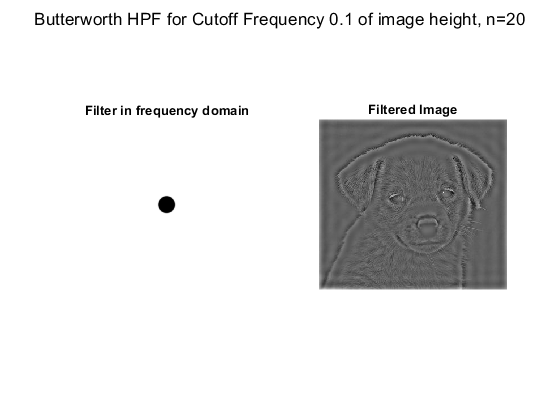

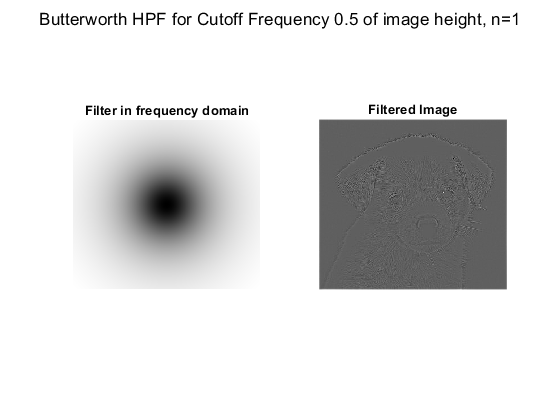

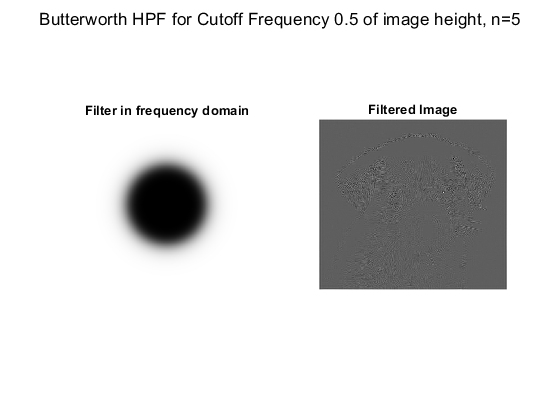

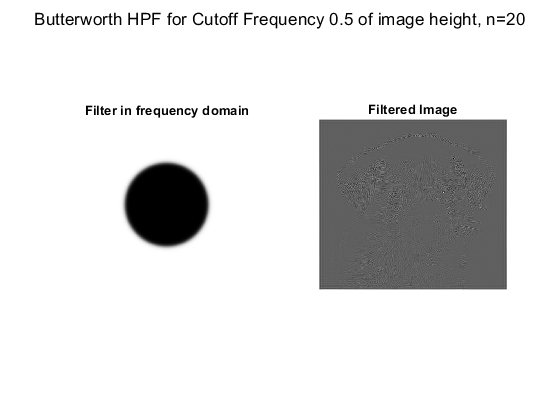

for j = [0.1, 0.5]
    for n = [1, 5, 20]
        D0 = j*im_size(1); 
        Filter = lp_hp_filters('btw','hp', P, Q, D0,n); % Calculate the LPF
        imtitle = sprintf('Butterworth HPF for Cutoff Frequency %.1f of image height, n=%d', j,  n);
        filter_plot(Filter, imtitle, F);
    end
end

6. Perform a Gaussian high pass filtering for cutoff frequencies (0.1, 0.3 and 0.7 of image height).

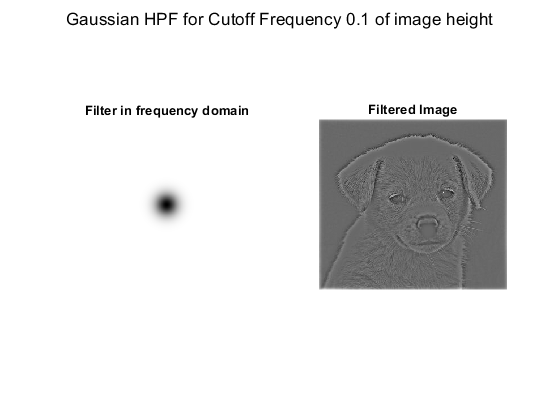

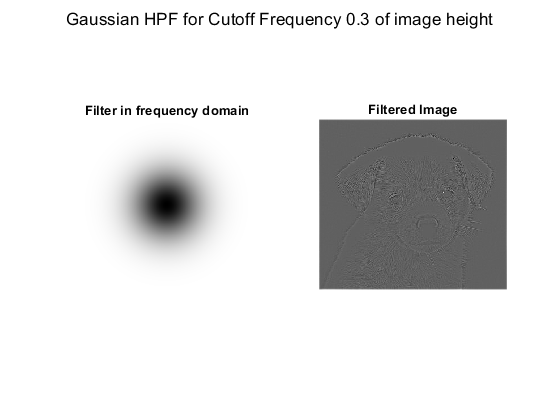

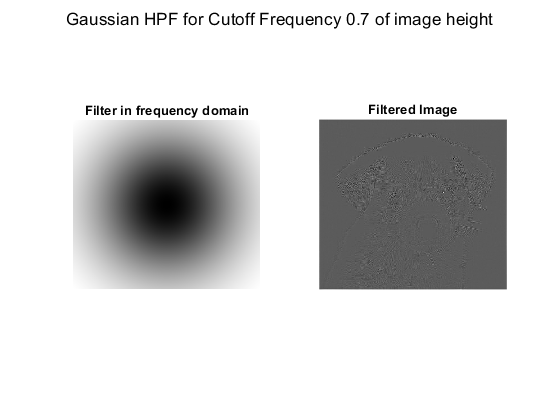

for j = [0.1, 0.3, 0.7]
    D0 = j*im_size(1); 
    n = 0;
    Filter = lp_hp_filters('gaussian','hp', P, Q, D0,n); % Calculate the LPF
    imtitle = sprintf('Gaussian HPF for Cutoff Frequency %.1f of image height', j);
    filter_plot(Filter, imtitle, F);
end

### Discussion

1. What can you observe when increasing the cut off frequency radius of the Ideal filter?

2. What can you observe when increasing the order of the Butterworth filter when the cut-off frequency remains the same?

3. Discuss the general performance of the Gaussian filters in comparison to the Ideal and Butterworth filters. You do not need to discuss each possible comparison case. Only discuss any interesting phenomenon or performance observations.

Note: Include your MATLAB code in your lab report along with your results.

function [] = filter_plot(Filter, imtitle, image)
% filter the image and plot the results
% Filter: filter wanted to apply
% imtitle: the figure title
% image: grayscale image wanted to be filtered
im_size=size(image); % Obtain the size of the image
P=2*im_size(1);Q=2*im_size(2); % Optaining padding parameters as 2*image size
FTIm=fft2(double(image),P,Q); % FT with padded size
Filtered_image=real(ifft2(Filter.*FTIm)); % multiply the FT of image by the filter and apply the IDFT
Filtered_image=Filtered_image(1:im_size(1), 1:im_size(2)); % Resize the image ( undo padding)
Fim=fftshift(FTIm); % move the origin of the FT to the center
FTI=log(1+abs(Fim)); % compute the magnitude (log to brighten display)
Ff=fftshift(Filter); % move the origin of the FT to the center
FTF=log(1+abs(Ff)); % compute the magnitude (log to brighten display)
figure;
sgtitle(imtitle);
subplot(1,2,1), imshow(FTF,[]), title('Filter in frequency domain'); % filter
subplot(1,2,2), imshow(Filtered_image,[]), title('Filtered Image'); % show the image
end